# Figure S7D

### **Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
    'siCtrl DMSO',2,2:6,1:9,[0 0 0]; %1      
    'siCCNA2 DMSO',3,2:6,1:9,[0 0 0]; %1      
    'siCCNB1/B2 DMSO',4,2:6,1:9,[0 0 0]; %1      
    'siCCNA2/B1/B2 DMSO',5,2:6,1:9,[0 0 0]; %1      

    'siCtrl TAK',2,7:11,1:9,[0 0 0]; %1      
    'siCCNA2 TAK',3,7:11,1:9,[0 0 0]; %1      
    'siCCNB1/B2 TAK',4,7:11,1:9,[0 0 0]; %1      
    'siCCNA2/B1/B2 TAK',5,7:11,1:9,[0 0 0]; %1  
    
    'siCtrl RO',7,2:6,1:9,[0 0 0]; %1      
    'siCtrl RO/TAK',7,7:11,1:9,[0 0 0]; %1      

    'siFBXO5 DMSO',6,2:6,1:9,[0 0 0]; %1  
    'siFBXO5 TAK',6,7:11,1:9,[0 0 0]; %1  

};


CCNA2 = [2 3 7 8];
CCNB1 = [4 5 9 10];
CCNB2 = [6 11];
load([dataDir filesep 'D123_data.mat'],'S');

framesPerHr = 60/12;
frameDrugAdded = 11;
frameEdU = 0;
timeStart = 3.5;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:}; 


for i = 1:length(S)
    S(i).frameDrugAdded = frameDrugAdded;
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
    S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

ALL_col = [2:11];

**Set gates**

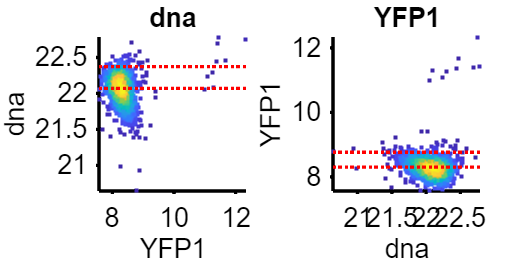


%% Set gates time after mitosis
conds = [1];

 gate = struct();

for c = 1:length(conds)
    cond = conds(c);
    gates = {'dna','YFP1'};
    plotting = {'YFP1','dna'};
    prctiles = {[50 95],[50 95]};
    
    figure('pos',[0 0 length(gates)*300 300 ])
    
    for i = 1:length(gates)
        inds = S(cond).POI_time(:,1) <= 2 & S(cond).POI_time(:,1) > 1 & S(cond).dna < 2^23;
        ydata = S(cond).(gates{i})(inds,:);
        xdata = S(cond).(plotting{i})(inds,:);
        
        gate.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
        
        subplot(1,length(gates),i)
        dscatter(log2(xdata),log2(ydata));
        hline( log2(gate.([gates{i} '_G1'])))
        ylabel(gates{i});
        xlabel(plotting{i});
        title(gates{i});


    end
    
    
end

**Gate cells**

xthresh = 7.5e6;
xrange = linspace(0,2e7,1000);
for i = 1:length(S)
    xdata = S(i).allDNA;
    [f, xi] = ksdensity(xdata,xrange);
    xi_trunc = xi(xi<xthresh);
    f_trunc = f(xi<xthresh);
    [~, maxi] = max(f_trunc);
    N_peak = xi_trunc(maxi);
    S(i).DNA_peak = N_peak;
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
   
    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .05;
        end
        
        
    end
    S(i).apcExpressGate = apcExpressGate;
   
    
end

**Cyclin B1B2 write**

ans = 2336

ans = 1592

ans = 909

ans = 561

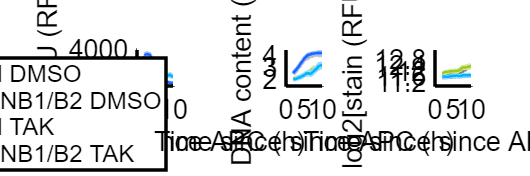

conds=[1 3  5 7 ] ;
poi_list = [2];


gateVals = {{},{},{},{},{},{},{},{}};
rangeVals = {{[]},{[]},{[]},{[]},{[]},{[]},{[]},{[]}};
name = {'since APC'};
edges = (0:(4/framesPerHr):15);
lims = {[0 10]};
gate_col = CCNB1;

%name_scatter = [pwd() '\Figs\siA2_scatter_no gate'];
name_scatter = [pwd() '\siB1B2_scatter_gate'];
name_mean = [pwd() '\siB1B2_mean_gate'];

stain_lims = [11 13.5];
% plot_IF_linear_gate(poi_list, conds, S, gateVals, rangeVals, edges, lims, name, conditions, gate_row,1);
plot_IF_linear_gate_save(poi_list, conds, S, gateVals, rangeVals, edges, lims, name, conditions, gate_col,1, name_scatter, name_mean, stain_lims, gate);

function plot_IF_linear_gate_save(poi_list, conds, S, gateVals, rangeVals, edges, lims, name, conditions, col_gate, gate_stain, save_scatter, save_mean, stain_lims, gate)
colors = [.5 .5 .5 ;.1 .4 1;.6 .8 .1; 0 .7 1];
for p = 1:length(poi_list)
    poiAligned=poi_list(p);
    f0 = figure('units','inches','pos',[0 0 4*length(conds) 3*4 ]);
    f1 = figure('units','inches','pos',[0 0 4*3 4 ]);
    
    legend_names = {};
    for i=1:length(conds)
        
        ind= any(S(conds(i)).fixedCol == col_gate,2) & ~isnan(S(conds(i)).dna) & ~isnan(S(conds(i)).POI_time(:,poiAligned)) & S(conds(i)).apcExpressGate   & ...
            gate_vals(S(conds(i)), gateVals{i}, rangeVals{i}) & (S(conds(i)).POI_realtime(:,3) > S(conds(i)).drug_time | isnan(S(conds(i)).POI(:,3)) );
        if gate_stain & (conds(i) == 2 | conds(i) == 6)
            ind = ind & S(conds(i)).FarRed1 < 2^12;
        elseif gate_stain & (conds(i) == 3 | conds(i) == 7)
            ind = ind & S(conds(i)).FarRed1 < 2^12;
        end
        xdata = S(conds(i)).POI_time(ind,poiAligned);
        ydata = [];
      
        ydata(:, 1) = (S(conds(i)).YFP1(ind));

        ydata(ydata(:,1) < .1,1) = .1;
        ydata(:,1) = (ydata(:,1));
        ydata(:, 2) = 2*(S(conds(i)).dna(ind)/S(conds(i)).DNA_peak);
        ydata(:, 3) = log2(S(conds(i)).FarRed1(ind));
        
        ind = xdata >= lims{p}(1) & xdata <= lims{p}(2);
        xdata = xdata(ind);
        ydata = ydata(ind,:);
        sum(ind)
      
        [binData, edges] = bin_xy(xdata, ydata, {'mean','median','std'},...
            'Edges',edges);
        midpoints = edges + (edges(2) -edges(1))/2;
        midpoints = midpoints(1:end-1);
        
     
        bin_gate = binData(2).numCells > 5;
        figure(f1)
        subplot(1,3,1)
        hold on
        shadedErrorBar(midpoints(bin_gate), binData(1).mean(bin_gate), 2*binData(1).std(bin_gate)./sqrt(binData(1).numCells(bin_gate)),'lineProps',{'Color',colors(i,:),'LineWidth',1.5})
       
        xlabel(['Time since ' name{p} ' (h)']);
        ylabel('Mean EdU (RFU)');
    ylim([0 4000]);
        xlim(lims{p});
        axis square
        
        subplot(1,3,2)
        hold on
      
        shadedErrorBar(midpoints(bin_gate), binData(2).mean(bin_gate), 2*binData(2).std(bin_gate)./sqrt(binData(2).numCells(bin_gate)),'lineProps',{'Color',colors(i,:),'LineWidth',1.5})
      
        xlabel(['Time since ' name{p} ' (h)']);
        ylabel('DNA content (N)');
        xlim(lims{p});
        ylim([1.5 4.5])
        axis square
        
        subplot(1,3,3)
        hold on
      
        shadedErrorBar(midpoints(bin_gate), binData(3).mean(bin_gate), 2*binData(3).std(bin_gate)./sqrt(binData(3).numCells(bin_gate)),'lineProps',{'Color',colors(i,:),'LineWidth',1.5})
       
        xlabel(['Time since ' name{p} ' (h)']);
        ylabel('log2[stain (RFU)]');
        xlim(lims{p});
        ylim(stain_lims)
        axis square
        yticks(11.2:.4:12.8)
        set(gca,'fontsize',16)
        if length(midpoints(bin_gate)) > 1
            legend_names = [legend_names, conditions(conds(i),1)];
        end
   
        
    end
    figure(f0)
    if ~isempty(save_scatter)
        print_pdf([save_scatter '_' name{p} '.pdf'])
    end
    figure(f1)
    subplot(1,3,1)
    legend(legend_names)
            hline(log2(gate.YFP1_G1(2)),'k')

    if ~isempty(save_mean)
        print_pdf([save_mean '_' name{p} '.pdf'])
    end
end
end
